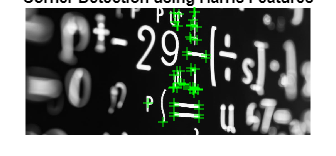

% Specify the full path to the image file
mathformula = imread("Math2cropped.jpg");

% Convert the image to grayscale
mathformulaAnalysis = im2gray(mathformula);

% Detect corner features using Harris features
corners = detectHarrisFeatures(mathformulaAnalysis);

% Detect blob features using SURF features
blobs = detectSURFFeatures(mathformulaAnalysis);

% Detect region-based features using regionprops
binaryImage = imbinarize(mathformulaAnalysis); % Binarize the image
labeledImage = bwlabel(binaryImage); % Label connected components
regions = regionprops(labeledImage, 'BoundingBox', 'Centroid'); % Get properties

% Display corner detection results
figure;
imshow(mathformulaAnalysis)
hold on
plot(corners.selectStrongest(50)); % Display the 50 strongest corners
title('Corner Detection using Harris Features');
hold off

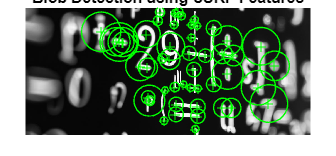


% Display blob detection results
figure;
imshow(mathformulaAnalysis)
hold on
plot(blobs.selectStrongest(50)); % Display the 50 strongest blobs
title('Blob Detection using SURF Features');
hold off

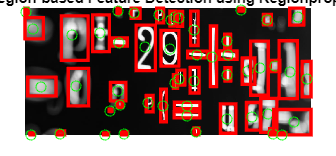


% Display region-based feature detection results
figure;
imshow(mathformulaAnalysis)
hold on
for k = 1 : length(regions)
    rectangle('Position', regions(k).BoundingBox, 'EdgeColor', 'r', 'LineWidth', 2); % Draw bounding box
    plot(regions(k).Centroid(1), regions(k).Centroid(2), 'go'); % Plot centroid
end
title('Region-based Feature Detection using Regionprops');
hold off